# Worksheet 2

Problem 1

u = [1 2 3]

u =      1     2     3


v = [4 5 6]

v =      4     5     6


% part 1
% a - yes, this make sense mathematically because you are dividing the same
% rows for both u and v
% b - I expect to get a vector with dimensions 1 x 3
% c - [.25 0.4 0.5]
u./v

ans =     0.2500    0.4000    0.5000


% part 2
% a - yes, this make sense mathematically because rows and colums math up
% b - I expect to get a vector with dimension 1x3
% c - [ 4 10 10]
u.*v

ans =      4    10    18


% part 3
% a - no, this does not make sense because the columns of 
% vector u(3) do not match the rows of vector v(1). This wil create an error
% u*v
% part 4 
% a - yes, it make sense because multiplying the transpose give you the
% 1x3 times 3x1 mathces up to give a scalar function
% b - I expect to get a vector with dimensions 1x1
% c - [32]
u*v.'

ans = 32

% part 5
% a - yes, it make sense becuse u' has a column of 1 and v has a row of 1
% meaning they are the same which leads to them giving an answer
% b - I expect to get a vector with dimensions 3x3
% c - answer displayed in workspace
u'*v

ans =      4     5     6
     8    10    12
    12    15    18


% part 6
% a - no, this does not make sense mathematically because the columns of
% the give matrix(3) does not mathc the rows of u(1).
% [1 2 4; 5 6 7]*u
% part 7
% a - yes, it make sense mathematically because the columns of the matrix
% (3) matches with the u(3) rows.
% b - I expect to get a vector with dimensions 2x1
% c - answer displace in work space
[1 2 4; 5 6 7]*u.'

ans =     17
    38


Problem 2

% part 1
A = [5 2 3; 1 -2 1; 1 1 -1]

A =      5     2     3
     1    -2     1
     1     1    -1


% part 2
b = [0 0 0]'

b =      0
     0
     0


% part 3
A\b

ans =      0
     0
     0


% part 4
lsqr(A, b)

The right hand side vector is all zero so lsqr
returned an all zero solution without iterating.


ans =      0
     0
     0


% part 5
% The results we get from part e does not agree with the results with what we get from c and d 
rref([A,b])

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0


Problem 3

% part a
A = [5 2 3;1 -2 1; 1 1 -1];
b = [1 2 1]';
x = A\b

x =     1.0556
   -0.8889
   -0.8333


% part b
% Notice the deteminant of B is 0 meaning B is not invertible
B = [1 2; -2 -4];
c = [1 -2]';
y = B\c

y =    NaN
   NaN


% part c
C = [5 2 3; 4 -8 4; 1 1 -1];
d = [1 8 1]';
z = C\d

z =     1.0556
   -0.8889
   -0.8333


% Part d  For parts a and c, we do have "redundant" information. This is because % the equations in part a are proportional to the equations in part c, with 
% the only difference between parts a and c being that in part c we have 
% the second equation from part a multiplied by 4 on both sides of the 
% equation. Thus, since we did the same things to each side of the 
% equation, all the solutions remain the same -- i.e. like changing y = x 
% to 2y = 2x.  
% For part b, we do not get a solution using the \ feature in matlab 
% because the determinaint of the matrix is equal to zero. This is because 
% this matrix has two equations that are the same, with the only difference 
% being that the second equation is proportional to the first by a factor 
% of -2. Thus, we have redundant information, which is why the determinaint 
% of this matrix is zero and why we do not get any solutions when using the 
% \ feature for this matrix in matlab. 

Problem 4

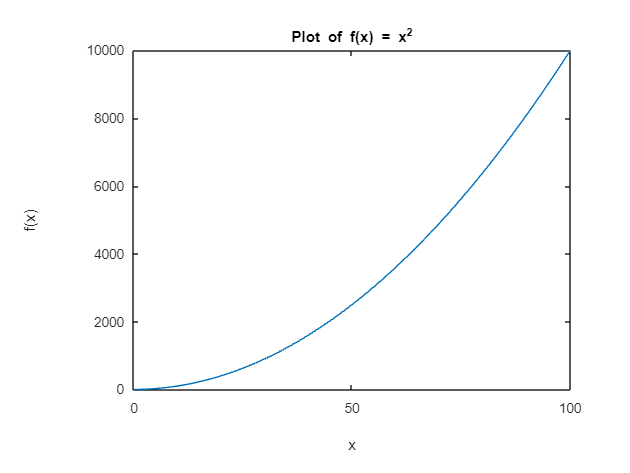

% 1
f = @(x) x.^2;
x = linspace(0,100);
plot(x,f(x));
xlabel('x');
ylabel('f(x)');
title('Plot of f(x) = x^2')

% 2
f_1 = @(x) f(x).*exp(-f(x))

f_1 = function_handle with value:
    @(x)f(x).*exp(-f(x))


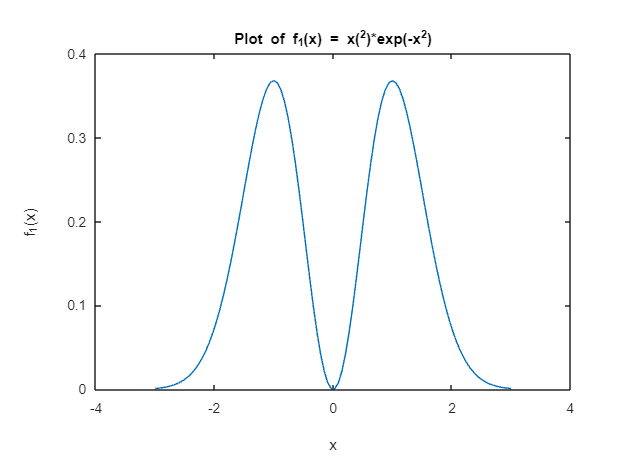

x = linspace(-3,3);
figure
plot(x,f_1(x));
xlabel('x');
ylabel('f_1(x)');
title('Plot of f_1(x) = x(^2)*exp(-x^2)')

% 3
f_2 = @(x) (tanh(x))./(sqrt(1+f(x)))

f_2 = function_handle with value:
    @(x)(tanh(x))./(sqrt(1+f(x)))


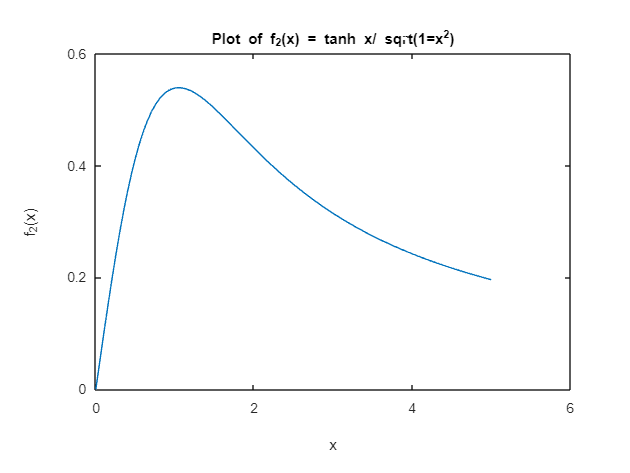

x = linspace(0,5);
figure
plot(x,f_2(x));
xlabel('x');
ylabel('f_2(x)');
title('Plot of f_2(x) = tanh x/ sqrt(1=x^2)')

% 4
f_3 = @(x) x - (x.^3)/(factorial(3))

f_3 = function_handle with value:
    @(x)x-(x.^3)/(factorial(3))


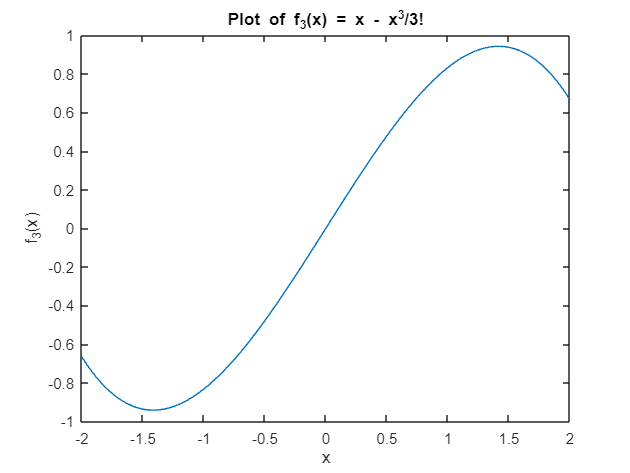

x = linspace(-2,2);
figure
plot(x,f_3(x));
xlabel('x');
ylabel('f_3(x)');
title('Plot of f_3(x) = x - x^3/3!')

% 5
f_4 = @(x) 1./(sqrt(abs(x.*log10(x))))

f_4 = function_handle with value:
    @(x)1./(sqrt(abs(x.*log10(x))))


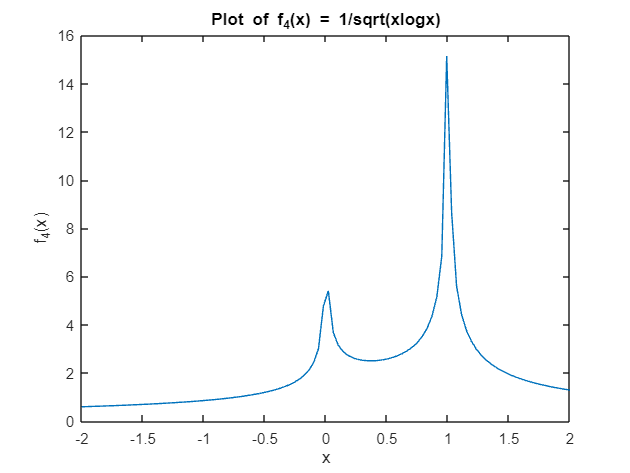

x = linspace(-2,2);
figure
plot(x,f_4(x));
xlabel('x');
ylabel('f_4(x)');
title('Plot of f_4(x) = 1/sqrt(xlogx)')

% 6
g = 1;
L = 1;
t = 3;
v = 0;
h = 3;
f_5 = @(t,v,h)[v; (g./L).*sin(pi.*t.*h)]

f_5 = function_handle with value:
    @(t,v,h)[v;(g./L).*sin(pi.*t.*h)]


result = f_5 (3,0,3)

result = 1.0e-14 *

         0
    0.1102


figure ();
x = linspace(0,100,500); 
y = f_0(x);
